# Experiment 1_2

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

## Part 6: aliasing in time domein

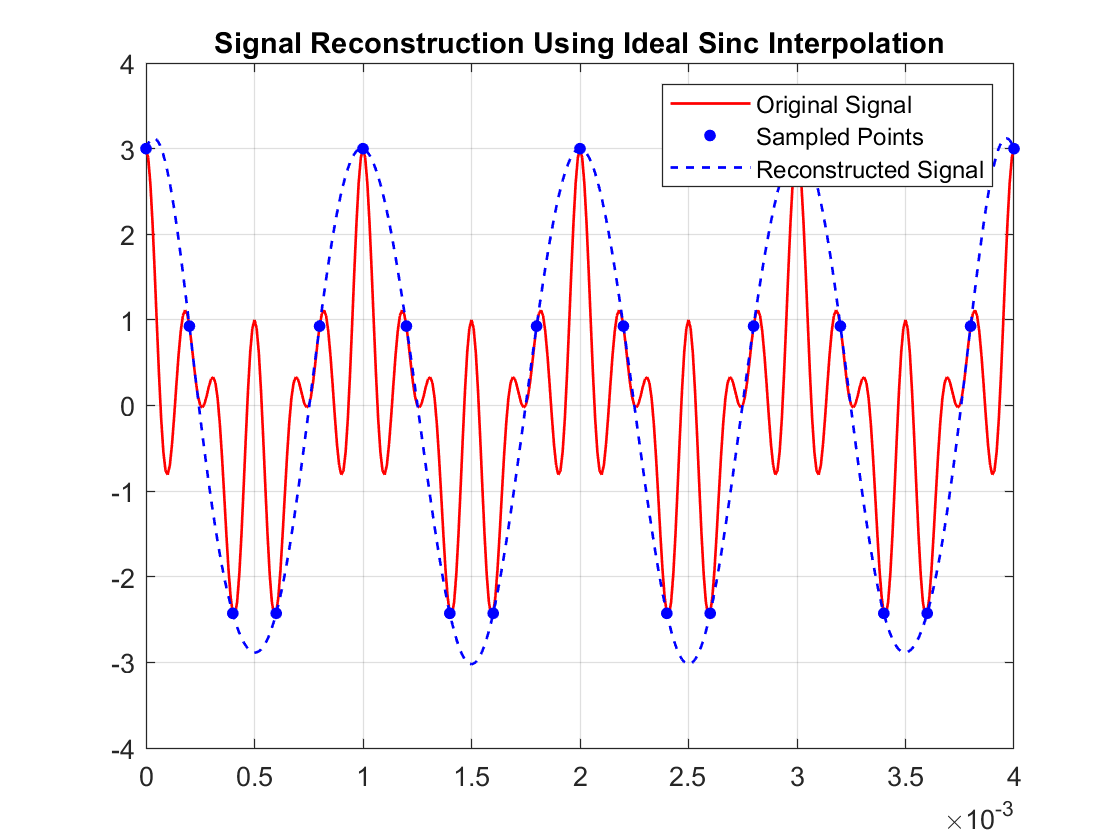

Ts = 0.00001;
t = 0:Ts:0.004;
x = cos(2*pi*1e3*t) + cos(8*pi*1e3*t) + cos(12*pi*1e3*t);
figure("Name", "original signal");
plot(t, x, LineWidth=1, Color='r');
title("original signal with samples");
hold on;
fs_low = 5e3;
T_low = 1/fs_low;
t_sampled = 0:1/fs_low:0.004;
x_sampled = cos(2*pi*1e3*t_sampled) + cos(8*pi*1e3*t_sampled) + cos(12*pi*1e3*t_sampled);
plot(t_sampled, x_sampled, '.b', 'MarkerSize', 15);


sinc_matrix = sinc((t' - t_sampled) / T_low);
x_reconstructed = sinc_matrix * x_sampled'; 

plot(t, x_reconstructed, '--b', 'LineWidth', 1); 
legend('Original Signal', 'Sampled Points', 'Reconstructed Signal');
title("Signal Reconstruction Using Ideal Sinc Interpolation");
grid on;

I expected that reconstructed signal would be a signal with lower frequency. Expectation was true as we can see in the figure above. It is because we didn't take enough samples from our signal and we have aliasing. Sampling rate is 5KHz which is lower than 2BW=12KHz.

## Part 7: aliasing in frequency domein (part 1)

## Part 8: aliasing in frequency domein (part 2)

## Part 9: multi-rate filter banks

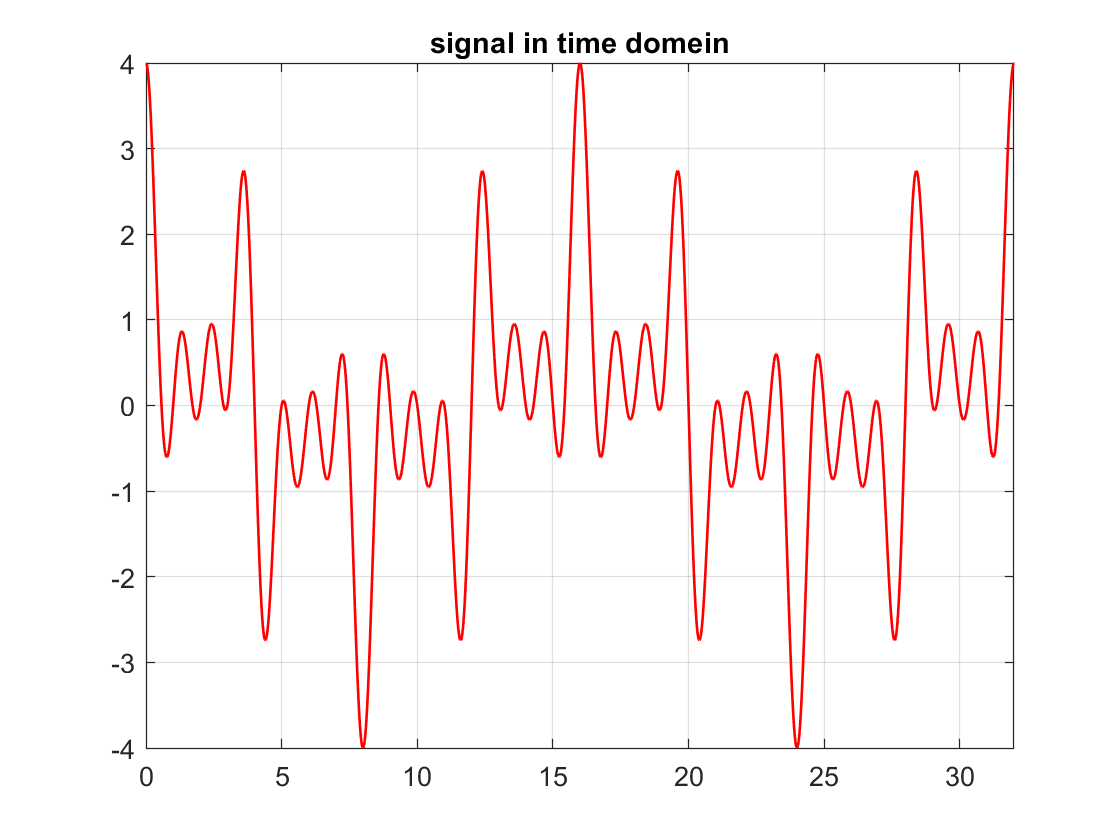

Ts = 16*0.0001;
t = 0:Ts:1000;
x = cos(2*pi*(1/16)*t) + cos(2*pi*(5/16)*t) + cos(2*pi*(9/16)*t) + cos(2*pi*(13/16)*t);
figure("Name", "signal in time domein");
plot(t, x, LineWidth=1, Color='r');
title("signal in time domein");
grid on;
xlim([0,2*16]);

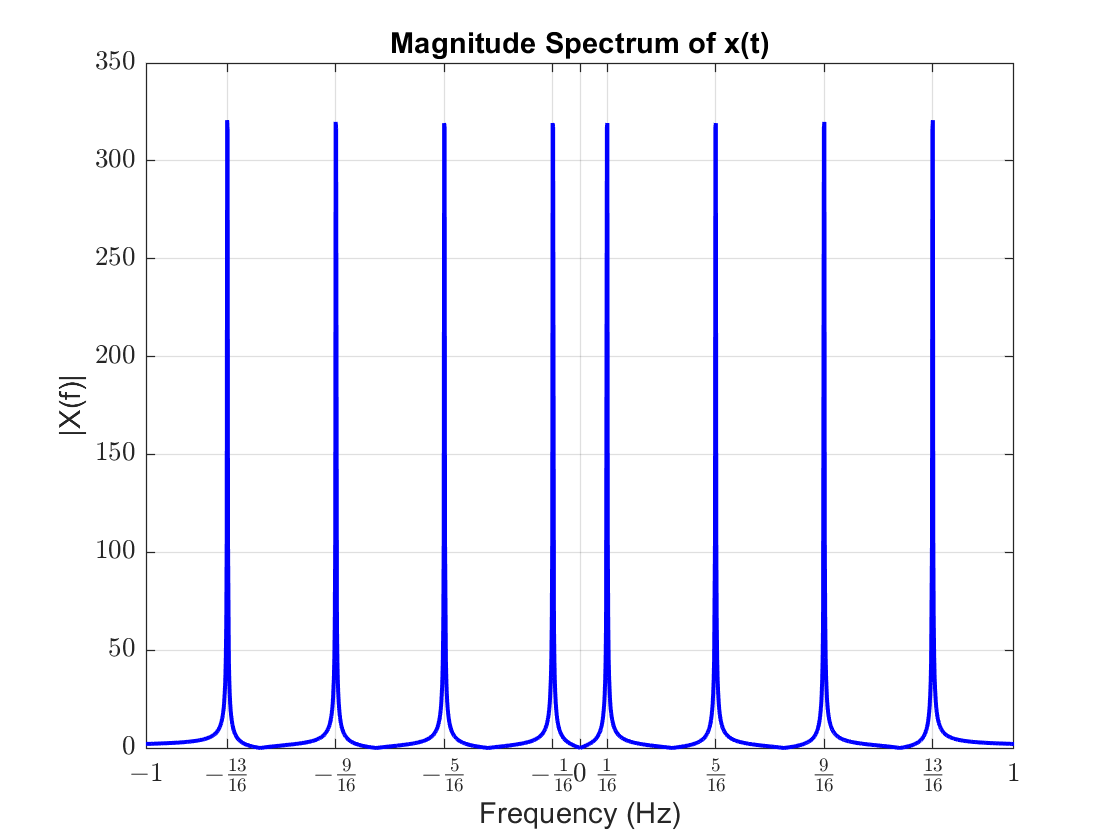

FT_x = Ts * fftshift(fft(x));

fs = 1/Ts; 
f = linspace(-fs/2, fs/2, length(FT_x)); 

figure("Name", "Frequency Domain");
plot(f, abs(FT_x), 'LineWidth', 1.5, 'Color', 'b');
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Magnitude Spectrum of x(t)");
grid on;
xlim([-1 1]);
xticks([-1, -13/16, -9/16, -5/16, -1/16, 0, 1/16, 5/16, 9/16, 13/16, 1]);
xticklabels({'$-1$', '$-\frac{13}{16}$', '$-\frac{9}{16}$', '$-\frac{5}{16}$', ...
             '$-\frac{1}{16}$', '$0$', '$\frac{1}{16}$', '$\frac{5}{16}$', ...
             '$\frac{9}{16}$', '$\frac{13}{16}$', '$1$'});
set(gca, 'TickLabelInterpreter', 'latex'); % Enable LaTeX formatting